# Battery State of Charge Estimation using Extended Kalman Filter and Equivalent Circuit Model

#### Please use the following to reference this work:

## F. Khanum, E. Louback, F. Duperly, C. Jenkins, P. J. Kollmeyer, and A. Emadi, “A Kalman Filter Based Battery State of Charge Estimation MATLAB Function,” in *2021 IEEE Transportation Electrification Conference & Expo*, 2021, pp. 484 - 489. 

The main goal of this script is to provide an example of battery State of Charge (SOC) estimation using the Extended Kalman Filter (EKF). The following script analyzes the battery's SOC and terminal voltage (Vt) during a driving cycle using a 2nd Order R-RC Equivalent Circuit Model considering the effects of battery surface temperature. The battery data used in this analysis is publicly available at [https://data.mendeley.com/datasets/4fx8cjprxm/1](https://data.mendeley.com/datasets/4fx8cjprxm/1).

clc; clear; close all;

### Load Experimental Data

First, load the battery time, voltage, current, and temperature data of a driving cycle experiment. This will serve as an input into the EKF_SOC_Estimation function (line 22). Since the real SOC cannot be directly measured for comparison against the EKF estimated SOC, it is calculated using coloumb counting (line 9).

In this example, the real data was previously organized into a structure type and then saved as a .mat file. Once the "load" command is executed (line 2), a "meas" (measurement) structure loads in the workspace, containing the driving schedule data. If the user of this script has the data saved in an Excel spreadsheet, for example, then use the command 'xlsread' and assign the data accordingly to the corresponding LiPoly structure (lines 3 to 6).

The battery manufacturer's nominal capacity can be used or the 25C C/20 calculated capacity. The nominal capacity used here should be the same as the variable $Cn$ in the EKF_SOC_Estimation function. 

load('04-12-19_04.45 765_LA92_40degC_Turnigy_Graphene.mat');
LiPoly.RecordingTime            = meas.Time;
LiPoly.Measured_Voltage         = meas.Voltage;
LiPoly.Measured_Current         = meas.Current;
LiPoly.Measured_Temperature     = meas.Battery_Temp_degC;

nominalCap                      = 4.81; % Battery capacity in Ah taken from data.
LiPoly.Measured_SOC             = (nominalCap + meas.Ah).*100./nominalCap;  % Calculate the SOC using Coloumb Counting for comparison

Depending on the data size, resampling may be needed to save computational time. In the following code lines, the data was resampled from 10 Hz to 1 Hz. The user may comment this part if desired. 

% Resample input data
LiPoly.RecordingTime            = LiPoly.RecordingTime(1:10:end);
LiPoly.Measured_Voltage         = LiPoly.Measured_Voltage(1:10:end);
LiPoly.Measured_Current         = LiPoly.Measured_Current(1:10:end);
LiPoly.Measured_Temperature     = LiPoly.Measured_Temperature(1:10:end);
LiPoly.Measured_SOC             = LiPoly.Measured_SOC(1:10:end);

**This script considers positive values of current as discharging currents, and negative as charging currents**. If the user's logged data has the opposite definition, then use the command in line 17 to reverse this definition, otherwise comment line 17. For plotting purposes, the sampling time is converted from seconds to hours.

% Current Definition: (+) Discharging, (-) Charging
LiPoly.Measured_Current_R       = - LiPoly.Measured_Current;

% Converting seconds to hours
LiPoly.RecordingTime_Hours      = LiPoly.RecordingTime/3600;

## EKF_SOC_Estimation Function

Given the measured current, voltage, SOC and temperature, the following function outputs the estimation of SOC and Vt, as well the errors with respect to the measurement.

[SOC_Estimated, Vt_Estimated, Vt_Error] = EKF_SOC_Estimation(LiPoly.Measured_Current_R, LiPoly.Measured_Voltage, LiPoly.Measured_Temperature);

### Plot the Results and Calculate Error

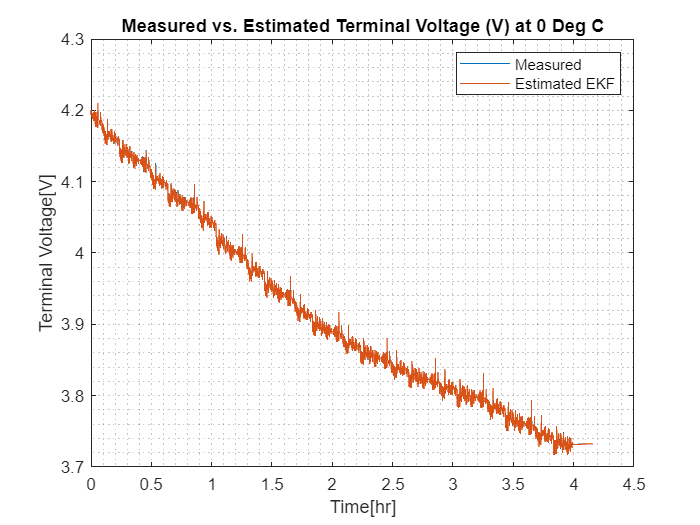

% Terminal Voltage Measured vs. Estimated
figure
plot(LiPoly.RecordingTime_Hours,LiPoly.Measured_Voltage);
hold on
plot(LiPoly.RecordingTime_Hours,Vt_Estimated);
hold off;
legend('Measured','Estimated EKF');
ylabel('Terminal Voltage[V]');xlabel('Time[hr]');
title('Measured vs. Estimated Terminal Voltage (V) at 0 Deg C')
grid minor

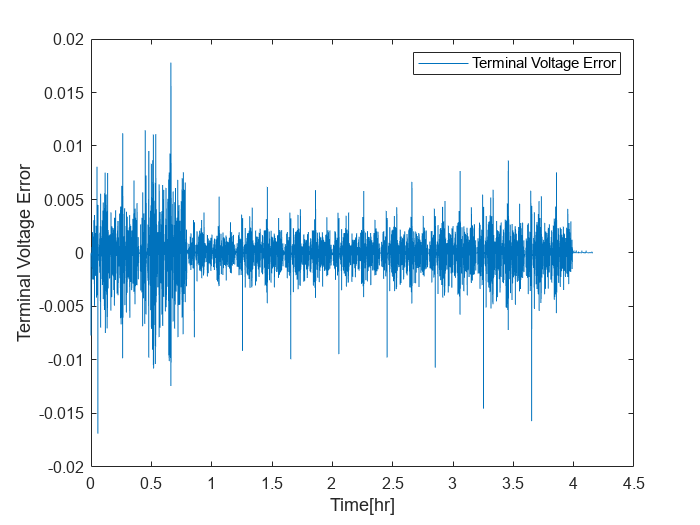

% Terminal Voltage Error
figure
plot(LiPoly.RecordingTime_Hours,Vt_Error);
legend('Terminal Voltage Error');
ylabel('Terminal Voltage Error');
xlabel('Time[hr]');

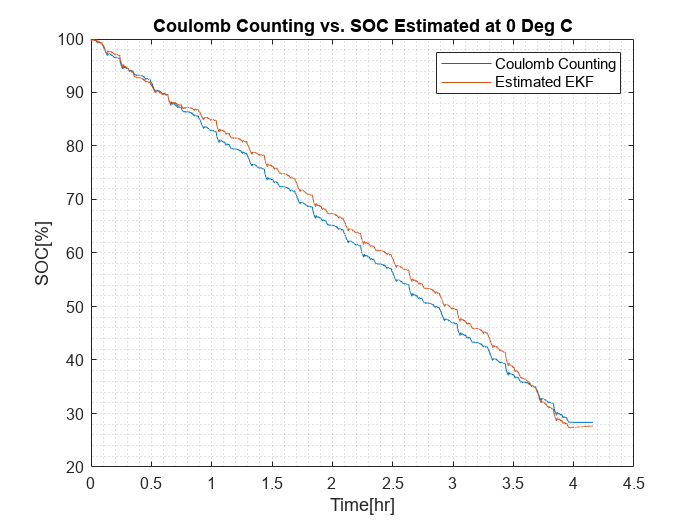

% SOC Coulomb Counting vs. Estimated
figure
plot (LiPoly.RecordingTime_Hours,LiPoly.Measured_SOC);
hold on
plot (LiPoly.RecordingTime_Hours,SOC_Estimated*100);
hold off;
legend('Coulomb Counting','Estimated EKF');
ylabel('SOC[%]');xlabel('Time[hr]');
title('Coulomb Counting vs. SOC Estimated at 0 Deg C')
grid minor

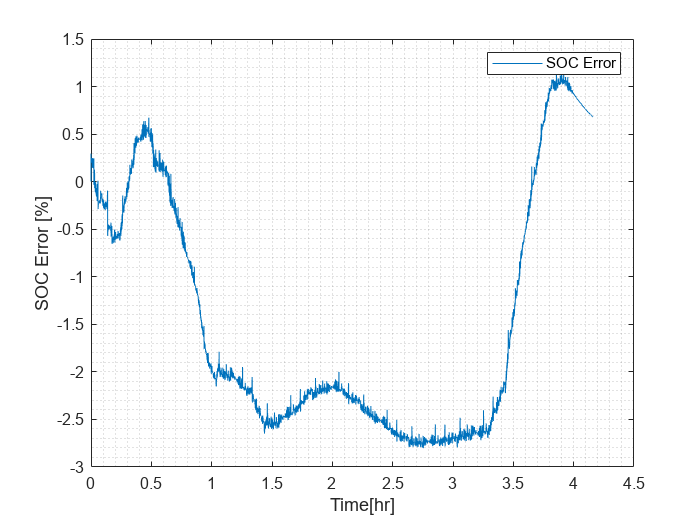

% SOC Error
figure
plot(LiPoly.RecordingTime_Hours,(LiPoly.Measured_SOC - SOC_Estimated*100));
legend('SOC Error');
ylabel('SOC Error [%]');
xlabel('Time[hr]');
grid minor

Calculate the root mean square error (RMSE) and the max error (MAX) of both the terminal voltage and SOC.

% Calculate RMSE and MAX of Vt and SOC
RMSE_Vt     = sqrt((sum((LiPoly.Measured_Voltage - Vt_Estimated).^2)) /(length(LiPoly.Measured_Voltage)))*1000 % mV

RMSE_Vt = 1.3154

RMSE_SOC    = sqrt((sum((LiPoly.Measured_SOC - SOC_Estimated*100).^2)) /(length(LiPoly.Measured_SOC))) % (%)

RMSE_SOC = 1.9440

Max_Vt      = max(abs(LiPoly.Measured_Voltage - Vt_Estimated))*1000 % mV

Max_Vt = 17.7890

Max_SOC     = max(abs(LiPoly.Measured_SOC - SOC_Estimated*100)) % (%)

Max_SOC = 2.8007